# Hands-On -  AR(2)  Stochastic Process: Correlation Function and the Spectral Power Density from Data - The Yule-Walker Equations

## Introduction

Given a stationary (in weak sense) white noise stochastic process


$$$\eta(\cdot) \sim WN(0,\lambda^2)$$$


with mean value $\text{E}\left[\eta(t)\right]=0$ and variance $\sigma^2_{\eta} = \lambda^2$, it is well known that an **Auto-Regressive stationary stochastic process AR(2)** is defined as


$$AR(2) \, \colon \quad
v(t) = a_1 \, v(t-1) +  a_2 \, v(t-2) + \eta(t)$$


or, equivalently, as


$$AR(2) \, \colon \quad
v(t) = \displaystyle \frac{1}{A(z)}\cdot \eta(t) \qquad A(z) = z^2-a_1 z-a_2$$


The **mean value** $\text{E}[v(t)]$ and the **variance** of the r.v. $v(t)$ are respectively


$$\bar{v} = \text{E}[v(t)] = 0 \qquad \qquad  \text{var}[v(t)] = \sigma^2_{v} = \frac{1-a_2}{(1+a_2)\,\left( 1-a_1-a_2\right) \,\left(1+a_1-a_2\right)} \cdot \lambda^2 \quad (\star)$$


where the parameters $a_1$ and $a_2$ must obey the constraints


$$\left\{
\begin{array}{ccl}
\left| a_2 \right| &<& 1 \\
a_1+a_2 &<& 1 \\
a_2-a_1 &<& 1
\end{array}
\right. \quad (\circ)$$


to guarantee the stationarity of the AR process.

The **autocorrelation function** of the stochastic process AR(2) takes on the expression (here the sketch of the proof):


$$\gamma(\tau) = \left\{\begin{array}{lcl}
 \frac{1-a_2}{(1+a_2)\,\left( 1-a_1-a_2\right) \,\left(1+a_1-a_2\right)} \cdot \lambda^2  &\quad & \tau = 0\\
\displaystyle \frac{a_1}{1-a_2} \cdot \gamma(0) & & \tau = \pm 1 \\
\left( \displaystyle \frac{a_1^2}{1-a_2} + a_2 \right)\cdot \gamma(0) & & \tau = \pm 2 \\
\left(K_1 p_1^{|\tau|}+ K_2 p_2^{|\tau|} \right)\cdot \gamma(0)& & \left| \tau \right| \ge 3
\end{array}
\right.$$


where $p_1$ and $p_2$ are the roots of the characteristic equation


$$A(z) = 0 \; \Longleftrightarrow \; z^2-a_1 z-a_2 = 0 \quad \Longleftrightarrow \quad p_{1,\, 2} = \displaystyle \frac{a_1 \pm \sqrt{a_1^2+4\,a_2}}{2}$$
 

$K_1$ and $K_2$ are constant coefficients to be determined from the initial conditions:


$$\left\{ \begin{array}{lcl}
K_1+K_2 =1 & \quad & \tau = 0\\
K_1 \cdot p_1 + K_2 \cdot p_2 = \displaystyle \frac{a_1}{1-a_2} & \quad & \tau = \pm1
\end{array}
\right.$$


The corresponding **spectral power density** is


$$\Gamma_{vv}(\omega) = 
\sum_{\tau=-\infty}^{+\infty} 
\gamma(\tau) e^{-j \omega \tau} \, = \frac{1}{
\left\vert A\left( e^{j\omega} \right) \right \vert^2} \cdot \lambda^2
\qquad
\forall \, \omega \in [-\pi,\pi] $$


## **Exercises**

Given the expression of the AR(2) r.v., 

- verify that the variance $\sigma^2_v$ of the r.v.  $v(t)$ assumes the expression in $(\star)$;

- prove also that the constraints in Eq. $(\circ)$ are sufficient conditions to have a stationary AR(2) process.

**Hint**: the solutions are at the end of this live script.

## A Practical Issue

Suppose we acquire a finite number $N$ of samples from a WSS stationary AR(2) process. How can we estimate the autocorrelation function and spectrum from the available data?

## Sampled Estimator of the Mean Value, the Variance and the Autocorrelation Function

We have already analysed the sampled estimators of mean value and variance. We recall them for convenience.

### Sample Average Estimator 

Given $N$ random variables $\, v(1)\,,\; v(2)\,,\; \ldots\,,\; v(N) \,$such that


$$\text{E} \left[ v(i) \right] = \mu_v\, , \quad i=1\,,\;2\,,\; \ldots\,,\; N$$


(i.e., with the same mean value) and						


$$\text{E} \left\{ \left[  v(i) - \mu_v \right] \, \left[ v(j) - \mu_v \right]\right\} = 0 \;, \quad \forall i \ne j$$


(i.e., the data are mutually uncorrelated), the **sampled-average estimator**					

				
$$\hat{\mu}_{v} = \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} v(i) $$


is an **unbiased estimator**, i.e. 


$$\text{E} \left[ \hat{\mu_{v}}\right] = \mu_{v}$$


### The Sample Variance

The sample variance of $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with known mean $\mu_v$ is defined as 


$$ \hat \sigma^2_{\mu_v,N}={\frac {1}{N}}\sum _{i=1}^{N}(v_{i}-\mu_v)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. 

In practice, **the mean value is often unknown** and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(v_{i}-\hat \mu_N)^2$$


### The Sample Autocorrelation Function

Given $N$ observations $\{v_i\}, i=1,\ldots,N$ of the random variable $V$ with **null mean value** $\mu_v = \text{E}\left[ v_i \right] = 0 \; \forall i$, the autocorrelation function $\gamma_{v}(\tau)$ can be estimated by mean of the following expression


$$\hat{\gamma}_v (\tau) = \left\{ \begin{array}{lcl}
\displaystyle \frac{1}{N-\tau} \sum_{n=0}^{N-\tau-1}\, v(n)\cdot v(n+\tau) & \quad & \tau \ge 0 \\
\hat{\gamma}_v(-\tau) & \quad & \tau <0
\end{array} \right. \qquad \left| \tau \right| \le N-1$$


It can be proven that it is an **unbiased estimator **(refer to [1] for details). Moreover, it can be proven that the variance of the estimate converges to zero as $N \to \infty$, so the estimate $\hat{\gamma}(\tau)$ is a **consistent estimate** of $\gamma(\tau)$ (refer to [1] for details).

## Estimated Autocorrelation Function from Data

Let us generate $N$ samples of a WSS stationary MA(1) stochastic process, with zero mean and variance $\lambda^2$.

Collect the data and then apply the sampled estimators.

clear variables
close all
clc

### Generate and Collect the Samples

Remember


$$AR(2) \, \colon \quad
v(t) = a_1 \, v(t-1) +  a_2 \, v(t-2) + \eta(t)$$


Ndata = 30000;    % select how many samples to collect and store

varWG = 2;      % select the white noise variance

AR2 = zeros(Ndata,1);    % preallocating the store for the samples 
                         % for the "v(t)" array for the AR(2) process
a2_AR = -0.9;     % select the value of the AR coefficient a_2 
                                          % according to the rule 
                                          %     -1 < a_2 < +1

a1_min = -1+a2_AR; a1_max = 1-a2_AR;      % the admissible extrema of the interval
                                          % for the a1_AR coefficient, with
                                          % the aim to guarantee the
                                          % stationarity of the AR(2)
                                          % process



a1_AR = 1.5; % the first coefficient a_1, according to the constraints
                                                     %     a_1 + a_2 < +1
                                                     %    -a_1 + a_2 < +1

N_init = 2; % the number of initial conditions, needed to initialise the generation of an AR(2) process realization                                                     
v_init = randn(N_init,1); % the initial conditions for the AR(2) process                                                    
                                                     

**Question**: What happens if we choose $a_2 =0$ ? What kind of stochastic process is it if we choose $a_2 =0$?

### The AR(2) Stochastic Stationary Process

Let's generate the data from the AR(2) process

% --- let's generate a realization for the AR process
Nbuffer = 5000;            % how many data to store the transient behaviour of the stochastic process
buffer = zeros(Nbuffer,1); % a buffer used to generate a stationary AR process, 
                           % regardless of any possible initial condition
buffer(1:N_init) = v_init;     % the initial condition for both the AR processes

eta = sqrt(varWG)*randn(Ndata+Nbuffer,1); % let's generate the white noise samples

ARbuffer = [buffer; AR2]; % merging the arrays
N = numel(ARbuffer); % how many data to be computed?

% ---- the AR(2) process ----
for ii = (N_init+1):N
    ARbuffer(ii) = a1_AR * ARbuffer(ii-1)+ a2_AR * ARbuffer(ii-2) + eta(ii);
end % for ii

AR2 = ARbuffer(Nbuffer+1:end); % let's throw away the transient part 
% of the process evolution, in order to "forget" the initial conditions


Let's estimate the **mean value** and the **variance** for the AR(2) process. The theoretical expression of the process variance is


$$\text{var} \left[ v(t) \right] = \frac{1-a_2}{(1+a_2)\,\left( 1-a_1-a_2\right) \,\left(1+a_1-a_2\right)} \cdot \lambda^2 $$


av_valAR2 = mean(AR2)      % the average value for the AR process

av_valAR2 = -0.0158

varAR2 = varWG * ((1-a2_AR)/((1+a2_AR)*(1-a2_AR-a1_AR)*(1+a1_AR-a2_AR))) % the theoretical expression of the process variance

varAR2 = 27.9412

sampled_varAR2 = var(AR2)     % the sampled variance

sampled_varAR2 = 29.6305

Run more than once, varying the variance of the process. Observe the convergence of the sampled estimates of the mean value and the variance to the effective values, when increasing the number of collected data.

### A Few Examples of AR(2) Stochastic Processes

Select different values for the parameteers $a_1$ and $a_2$ and explore the different behaviours of the autocorrelation function (and consequently of the spectrum)> For example, use the following values for the AR parameters:

- $a_1 = 1.25$, $a_2=-0.375$;

- $a_1 = -0.25$, $a_2=
0.375$;

- $a_1=0.5$, $a_2=-0.3125$;

- $a_1=-0.5$, $a_2=
0.3125$

### **What About the Autocorrelation Function?**

#### **Estimation of the Autocorrelation Function**

Ncorr1 =1024; % select the max value of tau in the estimation formula

Check if the maximum value for the lag $\tau$ is respecting the constraint $|\tau| \le N-1$, with $N$ the amount of available data.

errMSG = 'The max lag must be less or equal to (N-1), with N the amount of available data!'; % error message
assert((Ncorr1 <= (Ndata-1)), errMSG)

Let evaluate the estimate, using the MATLAB command `xcorr().`

Have a look to the command input and output variables, and to some application examples, using 


[gamma_AR, lags_AR] = xcorr(AR2, Ncorr1,'unbiased'); 
% unbiased estimation of the autocorr. function

p_12 = roots([1  -a1_AR  -a2_AR]); % poles of the A(z) polynomial
p1 = p_12(1); p2 = p_12(2);


As stated above in this live script:


$$A(z) = 0 \; \Longleftrightarrow \; z^2-a_1 z-a_2 = 0 \quad \Longleftrightarrow \quad p_{1,\, 2} = \displaystyle \frac{a_1 \pm \sqrt{a_1^2+4\,a_2}}{2}$$



$$\gamma(\tau) = \left(K_1 p_1^{|\tau|}+ K_2 p_2^{|\tau|} \right)\cdot \gamma(0)$$


where


$$\left\{ \begin{array}{lcl}
K_1+K_2 =1 & \quad & \tau = 0\\
K_1 \cdot p_1 + K_2 \cdot p_2 = \displaystyle \frac{a_1}{1-a_2} & \quad & \tau = \pm1
\end{array}
\right.$$


matA_K12 = [1, 1;...
            p1, p2]; % the system of linear equations 
                     % with K1 and K2 as variables
matB_K12 = [1;...
            a1_AR/(1-a2_AR)]; 
K12 = linsolve(matA_K12, matB_K12); % find the solution
K1 = K12(1); K2 = K12(2);           % the coefficients K1 and K2

% the theoretical expression of the autocorrelation function
gamma0 = varAR2; 

gammaAR2theo = zeros(size(lags_AR));
for jik = 1:numel(lags_AR)
    tau = abs(lags_AR(jik));
    gammaAR2theo(jik) = real((K1*p1^tau+K2*p2^tau))*gamma0;
end % for 
% the true autocorrelation function -- in case of complex poles, we have
% also complex coefficients K1 and K2 BUT the autocorrelation function MUST
% be real -- check that the samples of the sequence gammaAR2theo are always
% real numbers.


Now let's plot 

- the acquired samples of the AR process

- the samples of the estimated autocorrelation function

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);

subplot(2,1,1);

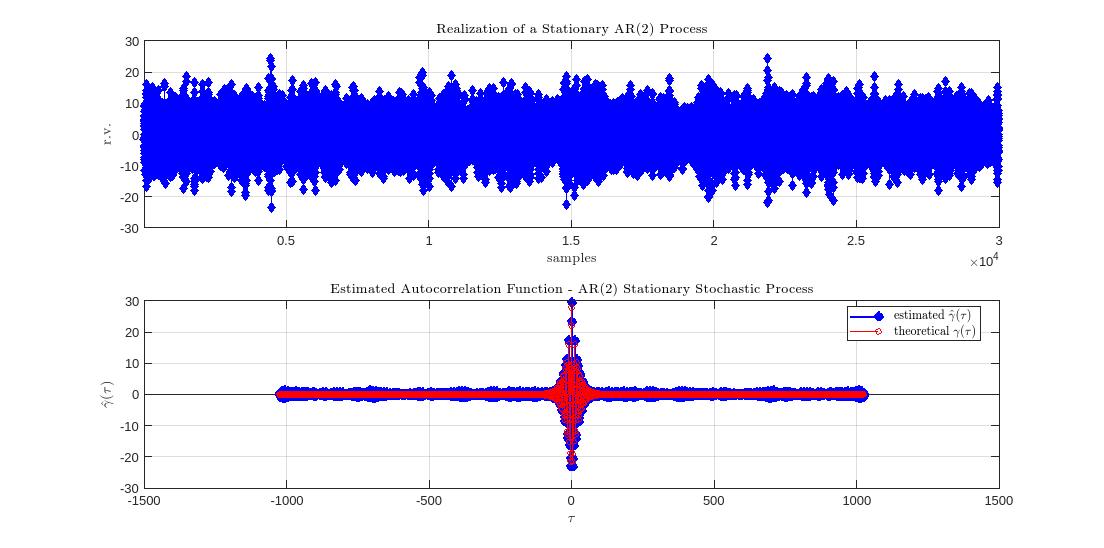

plot(AR2,'db-','MarkerSize',6, 'MarkerFaceColor','b','LineWidth',1.0);grid on;
title('Realization of a Stationary AR$(2)$ Process', 'Interpreter','latex');
xlabel('samples', 'Interpreter','latex');ylabel('r.v.', 'Interpreter','latex');
xlim([1, Ndata]); % setting the extremum values on the x-axis

subplot(2,1,2);
stem(lags_AR, gamma_AR,'b','filled', 'LineWidth', 1.5);
grid on; hold on; % the estimated autocorerlation function

stem(lags_AR, gammaAR2theo, 'r', 'MarkerSize',4,'LineWidth',1.0);

xlabel('$\tau$', 'Interpreter','latex');ylabel('$\hat{\gamma}(\tau)$',...
    'Interpreter','latex');
title('Estimated Autocorrelation Function - AR$(2)$ Stationary Stochastic Process',...
    'Interpreter','latex');
legend('estimated $\hat{\gamma}(\tau)$', 'theoretical $\gamma(\tau)$', 'Location', 'best', 'Interpreter', 'latex')

## Estimation of the Spectral Power Density from Data 

So far, we estimated the average value, the variance of the r.v. of the process and the autocorrelation function, just using the collected data. What about the **spectrum**?

Given the samples of the estimated autocorrelation function $\hat{\gamma}(\tau)$, the **estimate of the spectrum** can be evaluate  according to the so-called ***"periodogram"***** algorithm**

### Spectral Power Density Estimation: the Periodogram - A Recap

Given $2N-1$ samples of the autocorrelation function $\hat{\gamma}(\tau)\,,\quad \tau = -N+1\,,\; -N+2\,,\; \ldots\, N-2\,,\; N-1$, where $N$is the number of collected samples of the r.v.

- the Fourier transform of the autocorrelation function estimate is

$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$    (++)

- by substituting into $\hat{\Gamma}(\omega)$ the expression of $\hat{\gamma}(\tau)$ as function of the samples $v(n)$, and taking into account the properties of the autocorrelation function (the correlation function is an even function), the estimate $\hat{\Gamma}(\omega)$ can also be expressed as

$\hat{\Gamma}(\omega) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} \right\vert^{2} = \displaystyle \frac{1}{N}  \left\vert \hat{V}(\omega) \right\vert^{2} $  where $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $    (*)

- It can be proven  that the expected value of the estimated spectrum is a **smoothed version of the true spectrum**. Moreover, it suffers from the same **spectral leakage problems** which are due to the finite number of data points (refer to [1] for details). Hence **the periodogram is not a consistent estimate** of the true power density spectrum.

- Over the years, many other methods have been proposed, with the aim of obtaining a consistent estimate of the power spectrum, but these algorithms are outside the scope of this live script (and these topics are not included in the course). For details, please refer to a textbook on "Digital Signal Processing" such as [1].

#### The Algorithm: Using the DFT in Power Spectrum Estimation

- given $N$ samples of the r.v. $v$, evaluate $ \hat{V}(\omega) = \displaystyle \sum_{n=0}^{N-1}\, v(n)\,e^{-j\omega\,n} $, using the DFT algorithm, or more efficiently the FFT algorithm;


$$\hat{\Gamma}\left( 2\pi \displaystyle \frac{k}{N} \right) = \displaystyle \frac{1}{N} \left\vert  \sum_{n=0}^{N-1}\, v(n)\,e^{-j\,2 \pi \,n\,\frac{k}{N}} \right\vert^{2} \qquad k = 0\,,\;1\,,\;2\,,\;\ldots N-1$$


#### The Spectrum of the AR Process

Given the samples, collected in the `array AR2`, let's apply the Eq. (++) to estimate the spectrum:

- Evaluate the DFT of the autocorrelation function estimate sequence

AR2_FFT = fftshift(fft(gamma_AR));   % compute the FFT of 
                                     % the autocorrelation function samples
                                     % sequence

% rearrange the array of the FFT, by shifting 
% the zero-frequency component to the 
% center of the array.

- Compute the power spectrum estimate according to Eq. (++)


$$\hat{\Gamma}(\omega) = \displaystyle \sum_{\tau=-(N-1)}^{N-1}\; \hat{\gamma}(\tau)\,e^{-j\omega\,\tau}$$


**Proposal**: perform the spectrum estimation according to Eq. (*) [the periodogram] and compare the results.

powerSpectrumAR2 = abs(AR2_FFT); 
% the squared magnitude of the Fourier transform


- Compute the corresponding angular frequencies

omegaPSD = linspace(-pi,pi,numel(gamma_AR)); 
% (2 pi)/Ndata is the angular frequency resolution for the spectrum

z = tf('z', 1); % let's define a discrete-time transfer function W(z) = 1/A(z)
Wz = 1/(z^2-a1_AR*z-a2_AR) % the linear system, feeeded by the white noise process, describing the AR process

Wz =
 
          1
  -----------------
  z^2 - 1.5 z + 0.9
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties



Wejomega = abs(freqresp(Wz, omegaPSD)); % restituisce un array 3d di cui devo fare il reshape per scartare 2 delle dimensioni
Wejomega = reshape(Wejomega, [1, numel(omegaPSD)]); % reshaping Wejomega --> from 3d-array to 1d-array

W_ejom2 = Wejomega.^2; % the squared magnitude of the frequency response of W(z)

PSDtrue = W_ejom2 .* varWG; 
% the theoretical spectrum, evaluated at the angular frequencies in omegaPSD

- plotting the spectrum and compare with the theoretical expression $\Gamma_{vv}(\omega) = 
\sum_{\tau=-\infty}^{+\infty} 
\gamma(\tau) e^{-j \omega \tau} \, = \frac{1}{
\left\vert A\left( e^{j\omega} \right) \right \vert^2} \cdot \lambda^2
\qquad
\forall \, \omega \in [-\pi,\pi] $

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75]);
plot(omegaPSD,powerSpectrumAR2, 'LineStyle','-','LineWidth',1.5); % the estimated PSD
xlim([-pi, +pi]); % setting the extrema on the x-axis
grid on; hold on;
plot(omegaPSD,PSDtrue, 'LineStyle','--','LineWidth',2.5); % the estimated PSD
xlabel("Angular Frequency (rad/sample)", 'Interpreter','latex');
ylabel("Power/Frequency", 'Interpreter','latex');
title("Periodogram using FFT", 'Interpreter','latex');
legend('$\hat{\Gamma}(\omega)$', '$\Gamma(\omega)$', 'Location','best', 'Interpreter', 'latex')

#### **Remark**

As written above, the periodogram is an estimate that can be very rough. Compare with the theoretical spectrum.

## Solutions

**The AR variance**: Assume the AR process is a stationary stochastic process. Moreover, it is easy to prove that $\text{E}[v(t)] = 0$. 

Thus, the varaince of the AR r.v. takes on the expreession

$\text{var}[v(t)] = \text{E}[v^2(t)] = \text{E}\left[ \big(a_1 v(t-1) + a_2 v(t-2) + \eta(t) \big)^2\right]$        (S1)

Remember that $\text{var}[v(t)] = \gamma(0)$. Thus, after some algebraic manipulations of the previous expression, we get


$$\gamma(0) = a_1^2 \, \gamma(0)+a_2^2\, \gamma(0) + \lambda^2+ 2a_1\,a_2\,\gamma(1)$$


Consider now the expression of the autocorrelation function, considering two samples at temporal distance $\tau \ge0$


$$\gamma(\tau) = \text{E}\left[v(t)\cdot v(t-\tau) \right] = a_1 \gamma(\tau-1) + a_2 \gamma(\tau-2) + \text{E} \left[ v(t-\tau) \cdot \eta(t) \right]$$


For $\tau>0$, we get simply $\gamma(\tau) = a_1 \, \gamma(\tau-1) + a_2\, \gamma(\tau-2) $, so for $\tau=1$

$\gamma(1) = a_1\, \gamma(0) + a_2\,\gamma(-1) = a_1\, \gamma(0) + a_2\,\gamma(1) \quad \Longrightarrow \quad \gamma(1) = \displaystyle \frac{a_1}{1-a_2}\,\gamma(0)$        (S2)

Substituting the expression of $\gamma(1)$ in Eq. (S1) we obtain (after some algebraic manipulations) the variance of the AR process


$$\gamma(0) =  \frac{1-a_2}{(1+a_2)\,\left[ \left(1-a_2\right)^2-a_1^2\right]} \cdot \lambda^2 = \frac{1-a_2}{(1+a_2)\,\left( 1-a_1-a_2\right) \,\left(1+a_1-a_2\right)} \cdot \lambda^2 = \text{var}[v(t)] = \sigma^2_{v}$$


**The conditions on the parameters** for the process stationarity: 

Consider the variance


$$\text{var} \left[ v(t) \right] = \frac{1-a_2}{(1+a_2)\,\left( 1-a_1-a_2\right) \,\left(1+a_1-a_2\right)} \cdot \lambda^2 $$


If the parameters  obey the constraints


$$\left\{ \begin{array}{rcl}
(1-a_2) &>& 0 \\
(1+a_2) &>& 0\\
(1-a_2-a_1)&>&0\\
(1-a_2+a_1) &>&0
\end{array} \right.$$


then the variance assumes a positive value (as it must be).

## Sketch of the Proof

to be written

## References

[1] Proakis, John G. and Manolakis, Dimitris K.  * Digital Signal Processing (3rd Edition),* Prentice Hall,  1996.  